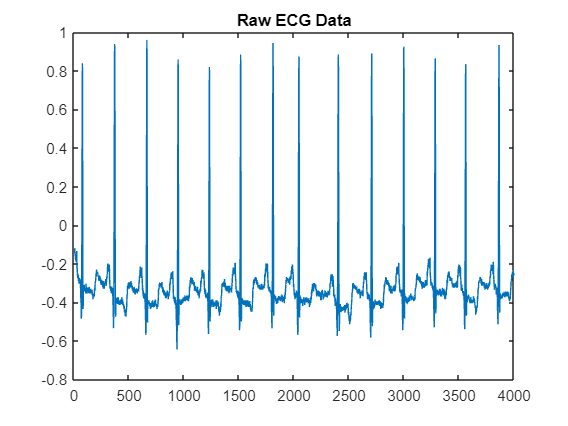

% Load ECG data
ecg_data = load("F:\IITM\Mtech 2_sem\Advanced_Modelling_Simulation_Lab\Exp2- R peak detection of ECG\100m.mat");
og = ecg_data.val(1, 1:4000) ./ 200;
plot(og);
title('Raw ECG Data');

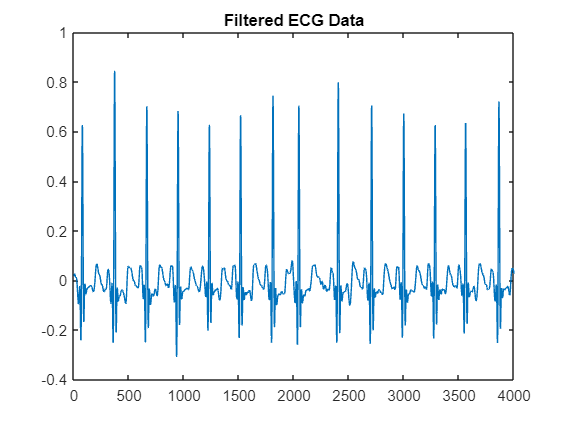


% Define sampling frequency
fs = 360;

% Bandpass filter parameters
fl = 5;  % Low cutoff frequency in Hz
fh = 20; % High cutoff frequency in Hz

% Design the bandpass filter
[b, a] = cheby1(4, 0.0001, [fl fh]/fs, 'bandpass');

% Apply the filter to the ECG signal
filtered_ecg = filtfilt(b, a, og);
figure;
plot(filtered_ecg);
title('Filtered ECG Data');

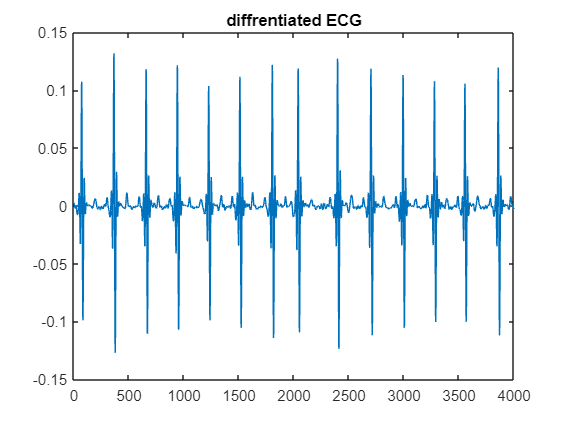


% Differentiation
different = diff(filtered_ecg);
plot(different)
title("diffrentiated ECG")

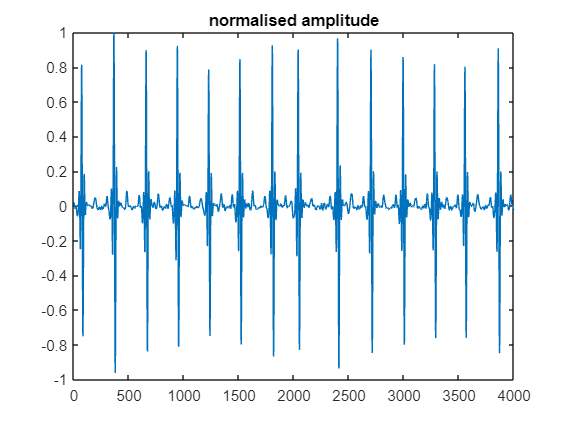


% Amplitude normalization
norm = different / max(abs(different));
plot(norm)
title('normalised amplitude')

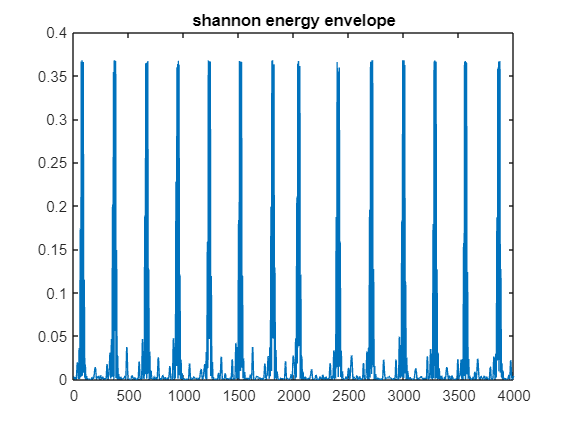


% Shannon energy envelope
norm_squared = norm.^2;
log_norm_squared = log(norm_squared);
shannon = norm_squared .* log_norm_squared * (-1);
plot(shannon)
title("shannon energy envelope")

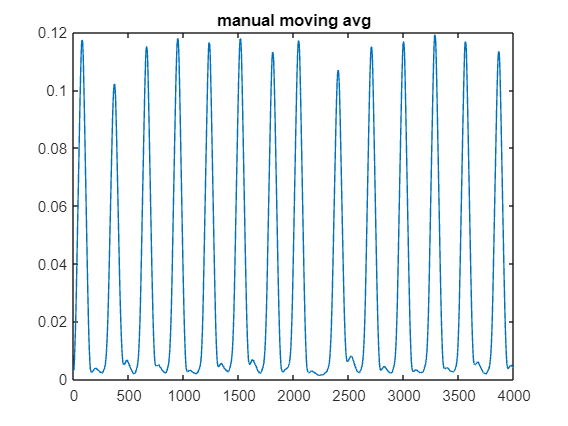


% Moving average
ma1 = (1/65) * ones(65, 1);
moving_avg = filtfilt(ma1, 1, shannon);
plot(moving_avg);
title("manual moving avg")

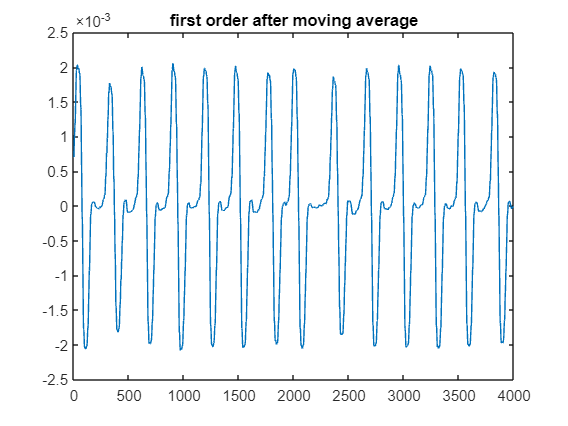


% Second differentiation
s2 = diff(moving_avg);
plot(s2);
title("first order after moving average")

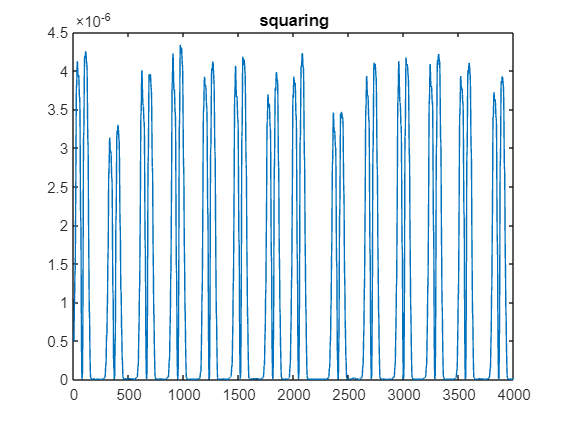


% Squaring
osqr = s2.^2;
plot(osqr)
title("squaring")


% Second moving average
q = (1/85) * ones(85, 1);
ma2 = filtfilt(q, 1, osqr);

% Find peaks in the second moving average
[pks, locs] = findpeaks(ma2);

% Preallocate the output array
o = zeros(size(locs));

% Find the true R peak in the neighborhood (25 samples) of detected points
for v = 1:numel(locs)
    j = 1;
    search_start = max(locs(v) - 25, 1);  
    search_end = min(locs(v) + 25, length(og)); 
    for i = search_start:search_end
        t(j) = og(i);
        j = j + 1;
    end
    [mag, pos] = max(t);
    o(v) = (pos - 1) + search_start;
end

% Display the final true position of R-peaks
disp('Final true position of R-peaks:')

Final true position of R-peaks:


disp(o);

          78         371         664         948        1232        1516        1810        2046        2404        2707        2999        3284        3561        3864



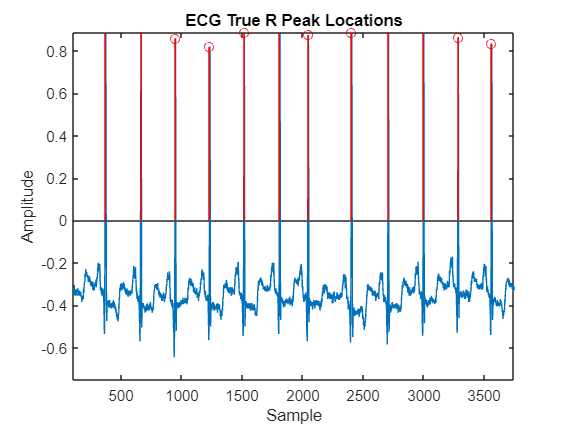


% Plot ECG R peak locations
g = 1:length(og);
figure;
plot(og);
hold on;
stem(g(o), og(o), 'r');
title('ECG True R Peak Locations');
xlabel('Sample');
ylabel('Amplitude');
hold off;

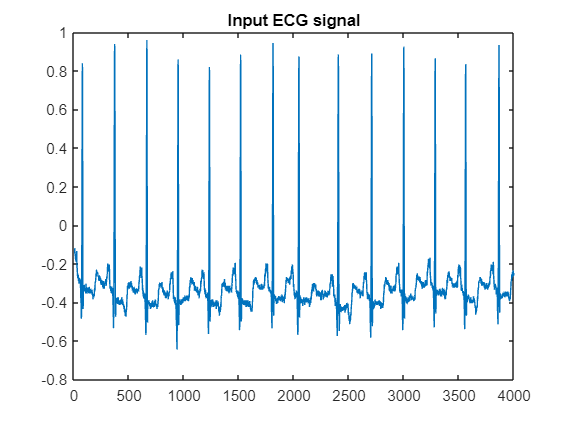

plot(og);
title("Input ECG signal")